# `Tratamiento de Datos Imprecisos`

### `Conceptos`

- `Movimiento del Polo:` A fines del siglo pasado se detectaron variaciones en la latitud del Observatorio de Berlín. Esto condujo a la realización de una campaña de observación de la que participaron varios observatorios de la época, que rápidamente pusieron de manifiesto que las variaciones de latitud y longitud observadas se debían al cambio de posición del eje de rotación dentro de la Tierra misma ("movimiento del polo"). Este movimiento del origen del sistema de referencia terrestre (polo de rotación) cambia de posición los paralelos y meridianos respecto de la superficie terrestre, en consecuencia cambian las coordenadas "latitud y longitud".  Este problema del movimiento del polo presenta un interés doble, encontrar los mecanismos geofísicos y astronómicos que lo generan, y encontrar la manera de corregir las determinaciones de latitud y longitud para contar con un sistema de referencia terrestre que está fijo a la Tierra.

- `Escala de tiempo UT1:` El Tiempo Universal UT1, es el tiempo del reloj que define la Tierra, que realiza un giro cada 24 horas. Presenta inestabilidades de corto periodo al nivel de 10^(-8), disminuyendo lentamente la duración del dí­a (casi 0.002 s/siglo). UT1 es uno de los productos del IERS (Servicio Internacional de Rotación de la Tierra y Sistemas de Referencia), basado en observaciones VLBI (interferometría de muy larga línea de base), que consiste en la observación de uno o varios objetos celestes con la ayuda de un gran número de radiotelescopios ubicados en distintas partes de la Tierra.

- `Escala de tiempo UTC:` UTC es una escala de tiempo de gran exactitud y estabilidad, basada en unos 450 relojes atómicos distribuidos por unos setenta y cinco laboratorios en todo el mundo. UTC utiliza como unidad de tiempo el segundo del Sistema Internacional (SI) de unidades.

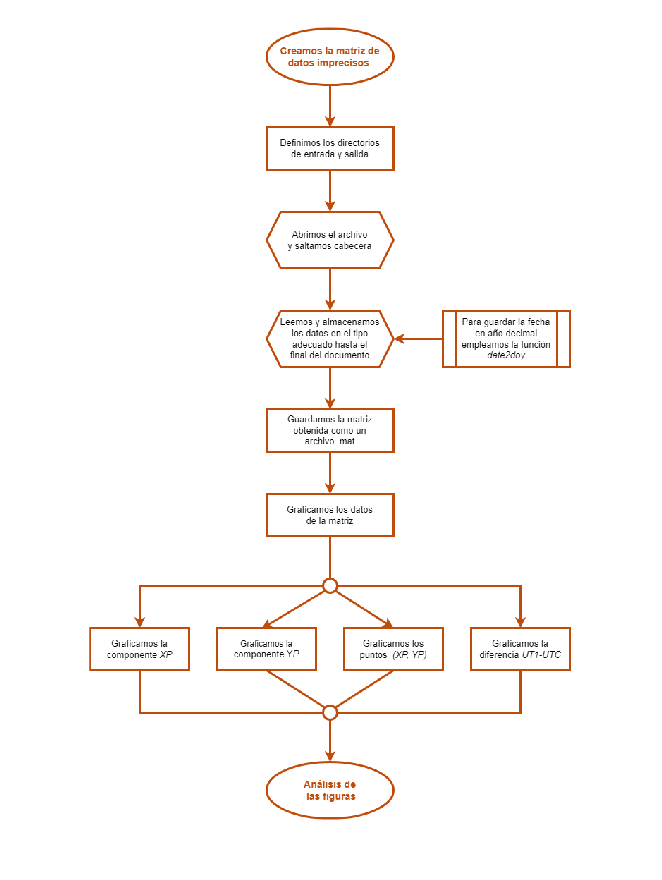

pathe_diag = '/home/desk-chaguarma/Documents/UNI/SAG/PRACTICAS/PR1/DIAGRAMAS/';

[im, map, alpha] = imread([pathe_diag 'PR1-B1.png']);
figure;
f = imshow(im);
set(f, 'AlphaData', alpha);

### `Tablas de datos`

En este proyecto, emplearemos un tipo de variable que almacena los datos como una tabla.

Definamos la tabla `tablaI` que almacenará los datos:

` fecha, X-polo, Y-polo, UT1-UTC, RMS-xp, RMS-yp, RMS-dt`. 

Tomando los datos del fichero BULLET.ERP, que almacena datos desde 2000-01-02 a  2018-09-22.

Primero, definimos el tipo de dato que almacenará cada columna y su nombre.

varTipos = ["double","double","double","double","double","double","double"];
varNames = ["Fecha", "X", "Y", "UT","RMS-X","RMS-Y","RMS-T"];

Segundo, una variable auxiliar en el que almacenaremos el número de columnas.

sz = [1 length(varNames)];

Finalmente, definimos la tabla con lo citado anteriormente.

tablaI = table('Size',sz,'VariableTypes',varTipos,'VariableNames',varNames);

A continuación, usamos la variable auxiliar `fila` para almacenar el nº de filas que tiene la tabla.

fila = 0;

### `Código Realizado`

Definimos en primer lugar la ruta donde se encuentra nuestro archivo de datos en la variable `directorio_raiz. `También una variable, `directorio_datos`*. *Finalmente, la ruta completa se almacena en `pathe_entrada`. 

directorio_raizs ='/home/desk-chaguarma/Documents/UNI/SAG/PRACTICAS/PR1/'; 
directorio_dats = 'IMPRECISOS/';
directorio_sal= 'SALIDA/';
directorio_diag= 'DIAGRAMAS/';

pathe_entrada=[directorio_raizs directorio_dats];
pathe_diag=[directorio_raizs directorio_diag];

El nombre del documento a trabajar lo almacenamos en `doc`. 

doc = "BULLET_A.ERP";

Abrimos el documento deseado con la función `fopen` habiendo concatenado la ruta y el nombre del archivo.

fidin = fopen(strcat(pathe_entrada,doc), 'r')

fidin = 5

Definimos una variable para quitar las primeras 6 líneas de documentación del archivo. Saltamos el nº de líneas deseado con un bucle.

elim = 6;
for i = 1:elim
    fgetl(fidin);
end

A partir del patrón del archivo, obtenemos datos de cada fila, con un bucle `while` con la condición que lea el archivo hasta que llegue al final de él. 

while ~feof(fidin)

Leemos la línea con la función `fgetl` y tomamos los tres primeros caracteres para controlar si hemos llegado al final del archivo. A partir de una función `if` controlamos si ha llegado al final.

  registro = fgetl(fidin);
  control_fin=registro(1:3);
  if control_fin=='EOF' %Puedes introducir este texto al final del doc como parada
      break

fila = 6839

  else

ans = 8×7 table
    Fecha       X          Y         UT        RMS-X     RMS-Y      RMS-T 
    _____    _______    _______    _______    _______    ______    _______

    2000     0.04354    0.37764     0.3546      6e-05     7e-05    1.2e-05
    2000      0.0436    0.37741    0.35385      7e-05     8e-05    1.1e-05
    2000     0.04345    0.37711    0.35324      7e-05     9e-05    1.2e-05
    2000     0.04322    0.37679    0.35276      8e-05     9e-05    1.8e-05
    2000     0.04324    0.37647    0.35235      9e-05     9e-05    1.8e-05
    2000     0.04351    0.37627    0.35195      8e-05     9e-05    1.8e-05
    2000     0.04374    0.37614    0.35154    0.00011     9e-05    1.6e-05
    2000     0.04376    0.37586     0.3511    0.00012    0.0001    1.8

Una vez comprobado que no es el final del documento, con la función `split`, dividimos la fila de datos que están separados por espacios y los almacenamos como un vector de caracteres en `registro`. Además, al añadir una nueva fila, aumentamos el contador `fila`,

      fila = fila + 1;
      registro = split(registro);
      registro = registro (1:13);

Para almacenar la fecha, primero obtenemos la cadena de la fecha (yyyy-MM-dd) siguiendo la disposición de los datos en el archivo. Tras ello, a partir de la función `date2doy` obtenida de [aquí](https://es.mathworks.com/matlabcentral/fileexchange/18316-date-to-decimal-day-of-year?s_tid=srchtitle_date2doy_1), transformamos la fecha a año con decimal.

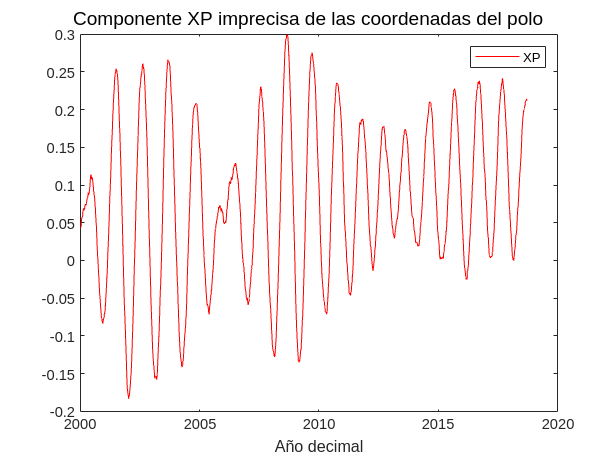

      fecha = strcat(registro(1),"-",registro(2),"-", registro(3));
      
      [doy,frac] = date2doy(datenum(fecha));
      
      frac = extractAfter(string(frac),1);

      fecha = strcat(registro(1),frac);

Finalmente, almacenamos los datos deseados en la matriz definida anteriormente. Almacenamos los datos en formato `double`.

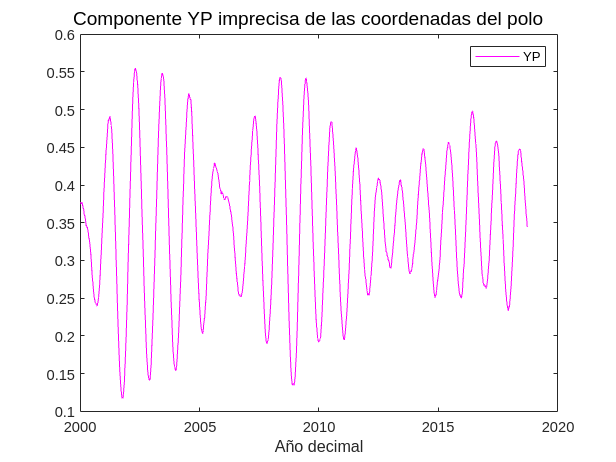

      tablaI(fila,:) = {double(string(fecha)), double(string(registro(6))), double(string(registro(7))), double(string(registro(8))), double(string(registro(11))), double(string(registro(12))), double(string(registro(13)))};
  end
end

fclose(fidin);

Aquí tenemos el numero de datos almacenados y la tabla obtenida.

fila
tablaI(1:8,:)

Guardamos la tabla `tablaI` de los datos imprecisos para compararla en otro archivo con los datos precisos.

save([directorio_raizs directorio_sal, 'tablaImprecisos.mat'],"tablaI")

### `Graficando Datos`

En esta gráfica representamos la variación de posición en X del polo durante el tiempo.

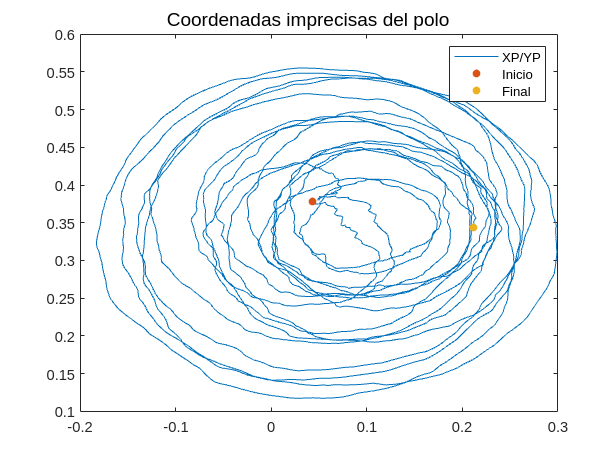

figure;
plot(tablaI.Fecha,tablaI.X,"red")
legend("XP")
xlabel('Año decimal')
sgtitle('Componente XP imprecisa de las coordenadas del polo')

En esta gráfica representamos la variación de posición en Y del polo durante el tiempo.

figure;
plot(tablaI.Fecha,tablaI.Y,"magenta")
legend("YP")
xlabel('Año decimal')
sgtitle('Componente YP imprecisa de las coordenadas del polo')

Se puede ver que ambas componentes varían de forma parecida, pero la componente `Y` toma valores mayores. Siendo el máximo para `X` de 0.3 y para `Y` 0.55. Parece que describe un periodo cada ciertos años, pero no tenemos suficientes datos para saberlo.

Ahora vemos la relación de posición de `X` e `Y`, y vemos que la posición del polo va variando describiendo circunferencias.

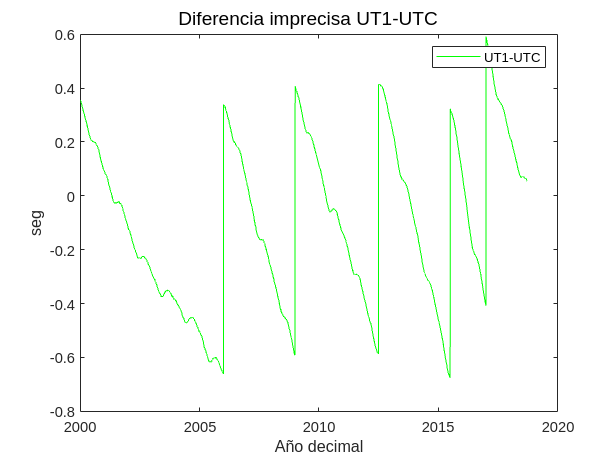

figure;

plot(tablaI.X,tablaI.Y)
hold on
plot(tablaI.X(1),tablaI.Y(1),".",'MarkerSize',16)
plot(tablaI.X(fila),tablaI.Y(fila),".",'MarkerSize',16)
legend("XP/YP","Inicio","Final")
sgtitle('Coordenadas imprecisas del polo')
hold off

Vemos que el polo describe elipses irregulares, superponiéndose.

Por último, graficamos las diferencias  de UT1, que es la corrección de UT0 por el efecto del movimiento polar en la longitud del sitio de observación, y UTC, que es el tiempo universal coordinado.

figure;
plot(tablaI.Fecha,tablaI.UT,"green")
legend("UT1-UTC")
xlabel('Año decimal')
ylabel('seg')
sgtitle('Diferencia imprecisa UT1-UTC')

Finalmente, para el tiempo observamos que su corrección hace una gráfica escalonada.

*Adrián Fernández Tejada - Adrián Sánchez Loureiro*

### `Funciones definidas`

Aquí tenemos la función citada anteriormente, que nos transforma la fecha a un número decimal.

function [doy,fraction] = date2doy(inputDate)
%DATE2DOY  Converts the date to decimal day of the year.
%   [doy,fraction] = date2doy(inputDate)
%
%   Descriptions of Input Variables:
%   inputDate:  Input date as a MATLAB serial datenumber
%
%   Descriptions of Output Variables:
%   doy: Decimal day of the year. For instance, an output of 1.5 would 
%       indicate that the time is noon on January 1.
%   fraction: Outputs the fraction of a year that has elapsed by the input
%       date.
%
%   Example(s):
%   >> [doy,frac] = date2doy(datenum('1/25/2004'));
%
%   See also:

% Author: Anthony Kendall
% Contact: anthony [dot] kendall [at] gmail [dot] com
% Created: 2008-03-11
% Copyright 2008 Michigan State University.

%Want inputs in rowwise format
[doy,fraction] = deal(zeros(size(inputDate)));
inputDate = inputDate(:);

%Parse the inputDate
[dateVector] = datevec(inputDate);

%Set everything in the date vector to 0 except for the year
dateVector(:,2:end) = 0;
dateYearBegin = datenum(dateVector);

%Calculate the day of the year
doyRow = inputDate - dateYearBegin;

%Optionally, calculate the fraction of the year that has elapsed
flagFrac = (nargout==2);
if flagFrac
    %Set the date as the end of the year
    dateVector(:,1) = dateVector(:,1) + 1;
    dateYearEnd = datenum(dateVector);
    fracRow = (doyRow - 1) ./ (dateYearEnd - dateYearBegin);
end

%Fill appropriately-sized output array
doy(:) = doyRow;
if flagFrac
    fraction(:) = fracRow;
end
end